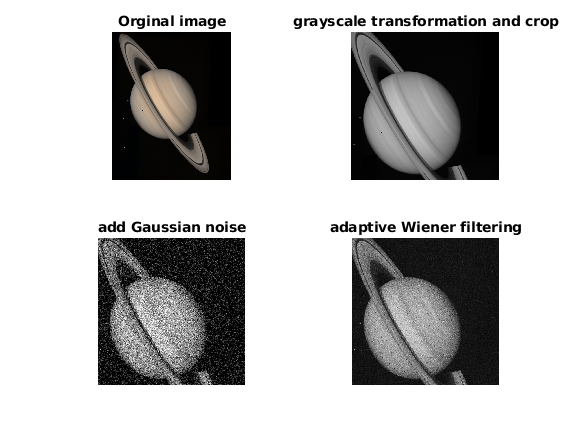


%Perform adaptive filtering on the image


 orginal_image = imread('saturn.png');% read the original color image
 I = rgb2gray(orginal_image);% grayscale transformation
 I = imcrop(I, [100, 100, 1024, 1024]);% cut
 J = imnoise(I,'gaussian', 0, 0.03);% add Gaussian noise
 [K, noise] = wiener2(J, [5, 5]);% adaptive Wiener filtering
 
figure; 
subplot(221), imshow(orginal_image),title('Orginal image'); 
subplot(222), imshow(I),title('grayscale transformation and crop'); 
subplot(223), imshow(J),title('add Gaussian noise'); 
subplot(224), imshow(K),title('adaptive Wiener filtering'); 